clear all;
clc;

load('1017_preprocessed_filtered_PCA.mat'); 
X = reduced_feature_matrix;  % PCA로 차원 축소된 특징 벡터
y_valence = labels_matrix(:, 1);  % Valence 라벨
y_arousal = labels_matrix(:, 2);  % Arousal 라벨
y_dominance = labels_matrix(:, 3);  % Dominance 라벨

% --- 데이터 분리 (70% 학습, 30% 테스트) ---
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

% --- 학습 데이터와 테스트 데이터 분리 ---
X_train = X(trainIdx, :);
X_test = X(testIdx, :);
y_train_valence = y_valence(trainIdx, :);
y_test_valence = y_valence(testIdx, :);
y_train_arousal = y_arousal(trainIdx, :);
y_test_arousal = y_arousal(testIdx, :);
y_train_dominance = y_dominance(trainIdx, :);
y_test_dominance = y_dominance(testIdx, :);

% --- 하이퍼파라미터 값 설정 (범위 확장) ---
num_learning_cycles = [50, 100, 200];  % 트리 개수
max_num_splits = [50, 200, 500];       % 트리의 최대 분할 개수
min_leaf_sizes = [1, 5, 10, 20];       % 최소 리프 노드 크기

mse_values_valence = [];
mse_values_arousal = [];
mse_values_dominance = [];
params_list = [];

% --- 하이퍼파라미터 튜닝 및 MSE 계산 ---
disp('하이퍼파라미터 튜닝 시작...');

하이퍼파라미터 튜닝 시작...


for cycles = num_learning_cycles
    for splits = max_num_splits
        for leaf_size = min_leaf_sizes
            disp(['NumLearningCycles: ', num2str(cycles), ', MaxNumSplits: ', num2str(splits), ', MinLeafSize: ', num2str(leaf_size)]);
            
            % --- 트리 템플릿 생성 ---
            tree_template = templateTree('MaxNumSplits', splits, 'MinLeafSize', leaf_size);
            
            % --- Random Forest 모델 학습 (Valence) ---
            rf_model_valence = fitrensemble(X_train, y_train_valence, 'Method', 'Bag', ...
                'NumLearningCycles', cycles, 'Learners', tree_template);
            y_pred_valence = predict(rf_model_valence, X_test);
            mse_valence = mean((y_pred_valence - y_test_valence).^2);
            mse_values_valence = [mse_values_valence; mse_valence];
            
            % --- Random Forest 모델 학습 (Arousal) ---
            rf_model_arousal = fitrensemble(X_train, y_train_arousal, 'Method', 'Bag', ...
                'NumLearningCycles', cycles, 'Learners', tree_template);
            y_pred_arousal = predict(rf_model_arousal, X_test);
            mse_arousal = mean((y_pred_arousal - y_test_arousal).^2);
            mse_values_arousal = [mse_values_arousal; mse_arousal];
            
            % --- Random Forest 모델 학습 (Dominance) ---
            rf_model_dominance = fitrensemble(X_train, y_train_dominance, 'Method', 'Bag', ...
                'NumLearningCycles', cycles, 'Learners', tree_template);
            y_pred_dominance = predict(rf_model_dominance, X_test);
            mse_dominance = mean((y_pred_dominance - y_test_dominance).^2);
            mse_values_dominance = [mse_values_dominance; mse_dominance];
            
            % 하이퍼파라미터 조합 저장
            params_list = [params_list; cycles, splits, leaf_size];
        end
    end
end

NumLearningCycles: 50, MaxNumSplits: 50, MinLeafSize: 1
NumLearningCycles: 50, MaxNumSplits: 50, MinLeafSize: 5
NumLearningCycles: 50, MaxNumSplits: 50, MinLeafSize: 10
NumLearningCycles: 50, MaxNumSplits: 50, MinLeafSize: 20
NumLearningCycles: 50, MaxNumSplits: 200, MinLeafSize: 1
NumLearningCycles: 50, MaxNumSplits: 200, MinLeafSize: 5
NumLearningCycles: 50, MaxNumSplits: 200, MinLeafSize: 10
NumLearningCycles: 50, MaxNumSplits: 200, MinLeafSize: 20
NumLearningCycles: 50, MaxNumSplits: 500, MinLeafSize: 1
NumLearningCycles: 50, MaxNumSplits: 500, MinLeafSize: 5
NumLearningCycles: 50, MaxNumSplits: 500, MinLeafSize: 10
NumLearningCycles: 50, MaxNumSplits: 500, MinLeafSize: 20
NumLearningCycles: 100, MaxNumSplits: 50, MinLeafSize: 1
NumLearningCycles: 100, MaxNumSplits: 50, MinLeafSize: 5
NumLearningCycles: 100, MaxNumSplits: 50, MinLeafSize: 10
NumLearningCycles: 100, MaxNumSplits: 50, MinLeafSize: 20
NumLearningCycles: 100, MaxNumSplits: 200, MinLeafSize: 1
NumLearningCycles: 100, Ma


% --- 최적 MSE 값 및 해당 파라미터 출력 ---
[best_mse_valence, best_idx_valence] = min(mse_values_valence);
[best_mse_arousal, best_idx_arousal] = min(mse_values_arousal);
[best_mse_dominance, best_idx_dominance] = min(mse_values_dominance);

best_params_valence = params_list(best_idx_valence, :);
best_params_arousal = params_list(best_idx_arousal, :);
best_params_dominance = params_list(best_idx_dominance, :);

disp('--- 최적 MSE 및 파라미터 ---');

--- 최적 MSE 및 파라미터 ---


disp(['Valence 최적 MSE: ', num2str(best_mse_valence)]);

Valence 최적 MSE: 1.6532


disp(['Valence 최적 파라미터: NumLearningCycles = ', num2str(best_params_valence(1)), ...
    ', MaxNumSplits = ', num2str(best_params_valence(2)), ', MinLeafSize = ', num2str(best_params_valence(3))]);

Valence 최적 파라미터: NumLearningCycles = 50, MaxNumSplits = 500, MinLeafSize = 20



disp(['Arousal 최적 MSE: ', num2str(best_mse_arousal)]);

Arousal 최적 MSE: 1.2296


disp(['Arousal 최적 파라미터: NumLearningCycles = ', num2str(best_params_arousal(1)), ...
    ', MaxNumSplits = ', num2str(best_params_arousal(2)), ', MinLeafSize = ', num2str(best_params_arousal(3))]);

Arousal 최적 파라미터: NumLearningCycles = 200, MaxNumSplits = 200, MinLeafSize = 20



disp(['Dominance 최적 MSE: ', num2str(best_mse_dominance)]);

Dominance 최적 MSE: 1.4137


disp(['Dominance 최적 파라미터: NumLearningCycles = ', num2str(best_params_dominance(1)), ...
    ', MaxNumSplits = ', num2str(best_params_dominance(2)), ', MinLeafSize = ', num2str(best_params_dominance(3))]);

Dominance 최적 파라미터: NumLearningCycles = 200, MaxNumSplits = 200, MinLeafSize = 20


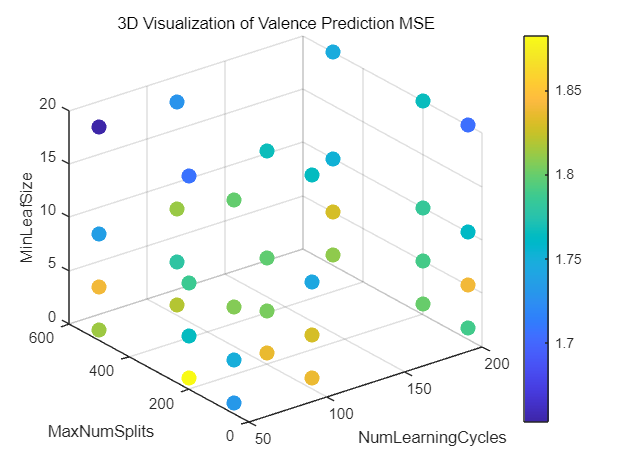


% --- 3차원 그래프 (Valence) ---
figure;
scatter3(params_list(:,1), params_list(:,2), params_list(:,3), 100, mse_values_valence, 'filled');
xlabel('NumLearningCycles');
ylabel('MaxNumSplits');
zlabel('MinLeafSize');
title('3D Visualization of Valence Prediction MSE');
colorbar;
grid on;
saveas(gcf, 'RF_Valence_3D_MSE.jpg');  % Valence 그래프 저장

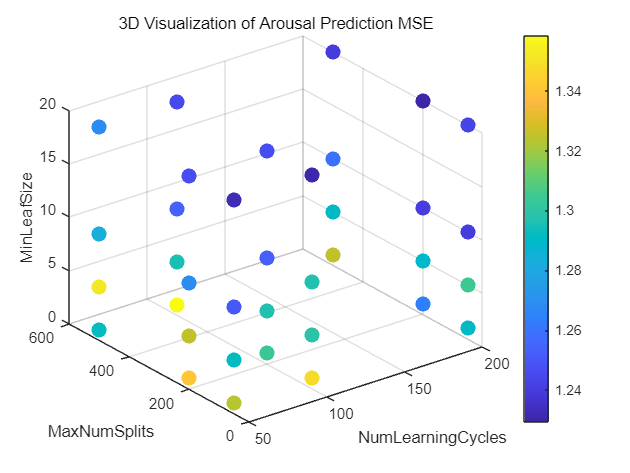


% --- 3차원 그래프 (Arousal) ---
figure;
scatter3(params_list(:,1), params_list(:,2), params_list(:,3), 100, mse_values_arousal, 'filled');
xlabel('NumLearningCycles');
ylabel('MaxNumSplits');
zlabel('MinLeafSize');
title('3D Visualization of Arousal Prediction MSE');
colorbar;
grid on;
saveas(gcf, 'RF_Arousal_3D_MSE.jpg');  % Arousal 그래프 저장

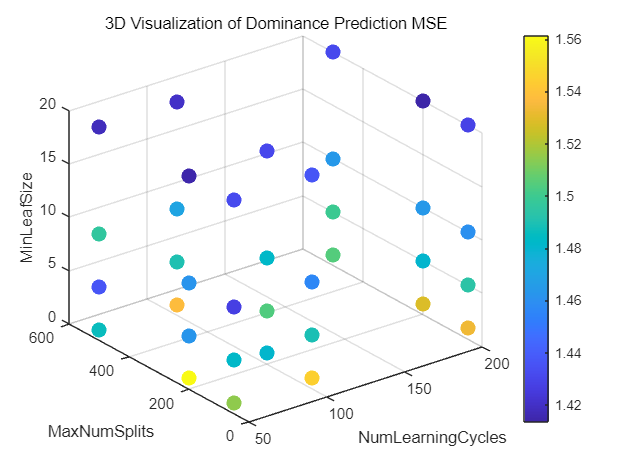


% --- 3차원 그래프 (Dominance) ---
figure;
scatter3(params_list(:,1), params_list(:,2), params_list(:,3), 100, mse_values_dominance, 'filled');
xlabel('NumLearningCycles');
ylabel('MaxNumSplits');
zlabel('MinLeafSize');
title('3D Visualization of Dominance Prediction MSE');
colorbar;
grid on;
saveas(gcf, 'RF_Dominance_3D_MSE.jpg');  % Dominance 그래프 저장